# An Introduction to First Order Plus Dead Time Models

A first-order linear system with time delay is a common empirical description of many stable dynamic processes. The First Order Plus Dead Time (FOPDT) model is used to obtain initial controller tuning constants. The widget below demonstrates the effect of the three adjustable parameters in the FOPDT equation: the gain $K_p$, time constant $\tau_p$, and dead time $ \theta_p$. Sample data from the TCLab is shown as well to show how FOPDT models represent measured data.

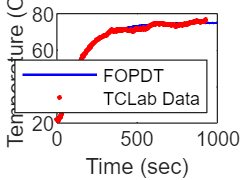

clc; clear all; close all;
clf
figure(1)
K = 71;
Tau = 140;
Theta =  15;

tclab_time = xlsread('tclab_time.xlsx');
tclab_temp = xlsread('tclab_temp.xlsx');
n = 1000;
time = linspace(1, n, n);
delay = ones(1, n);
for i=1:n
    if time(i)<Theta
        delay(i) = 0;
    end
end
y = tclab_temp(1) + .75 * K * delay .* (1.0-exp(-(time-Theta)/Tau));
plot(time, y, 'b-', tclab_time, tclab_temp, 'r.', "linewidth", 1)
legend('FOPDT', 'TCLab Data', 'location', 'southeast')
xlabel('Time (sec)')
ylabel('Temperature (C)')

After gaining an intuitive understanding of how the parameters influence the step response, it is important to understand the mathematical FOPDT equation. The equation


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables $y(t)$ and $u(t)$ and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


## Process Gain, $K_p$

The process gain is the change in the output *y* induced by a unit change in the input $u$. The process gain is calculated by evaluating the change in $y(t)$ divided by the change in $u(t)$ at steady state initial and final conditions.


$$K_p = \frac{\Delta y}{\Delta u} = \frac{y_{ss_2}-y_{ss_1}}{u_{ss_2}-u_{ss_1}}$$


The process gain affects the magnitude of the response, regardless of the speed of response.

## Process Time Constant, $\tau_p$

Given a change in $u(t) = \Delta u$, the solution to the linear first-order differential (without time delay) becomes:


$$y(t) = \left( e^{-t / \tau_p} \right) y(0) + \left( 1 - e^{-t / \tau_p} \right) K_p \Delta u$$


If the initial condition $y(0)=0$ and at $ t=\tau_p$, the solution is simplified to the following.


$$y\left( \tau_p \right) = \left( 1 - e^{-\tau_p / \tau_p} \right) K_p \Delta u = \left( 1 - e^{-1} \right) K_p \Delta u = 0.632 K_p \Delta u$$


**Analytic Solution Derivation with Laplace Transforms**

Start with the linear differential equation with time delay:


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t\right)$$


Perform a Laplace transform on each part of the equation (Use Laplace transform tables):


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \tau_p \left(s Y(s) - y(0)\right)$$



$$\mathcal{L}\left(-y(t)\right) = -Y(s)$$



$$\mathcal{L}\left(K_p u\left(t\right)\right) = K_p U(s)$$


If the input $U(s)$ is a step function of size $\Delta u$ then:


$$U(s) = \frac{\Delta u}{s}$$


Combining all of the individual Laplace transforms, the equation in Laplace domain with zero initial condition $y(0)=0$ is then:


$$\tau_p \, s \, Y(s) = -Y(s) + K_p \frac{\Delta u}{s}$$


At this point, the equation is algebraic and can be solved for $Y(s)$ by combining terms on each side:


$$\tau_p \, s \, Y(s) + Y(s) = K_p \frac{\Delta u}{s}$$


and factoring out the $Y(s)$ term:


$$Y(s) \left(\tau_p \, s + 1\right) = K_p \frac{\Delta u}{s}$$


A final steps are to isolate $Y(s)$ on the left side of the equation and perform an inverse Laplace transform to return to the time domain:


$$Y(s) = K_p \frac{\Delta u}{s\,\left(\tau_p \, s + 1\right)}$$



$$\mathcal{L}^{-1}\left(Y(s)\right) = y(t) =  K_p \left( 1-\exp \left( 1-\frac{ t  } { \tau_p } \right) \right) \, \Delta u$$


The process time constant is therefore the amount of time needed for the output to reach $(1-exp(-1))$ or *63.2%* of the way to steady state conditions. The process time constant affects the speed of response.

# Time Delay in Dynamic Systems ($\theta_p$)

The time delay is expressed as a time shift in the input variable $u(t)$.


$$u\left(t-\theta_p\right)$$


Suppose that that input signal is a step function that normally changes from 0 to 1 at time = 0 but this shift is delayed by *5 sec*. The input function $u(t)$ and output function *y(t)* are time-shifted by *5 sec*. The solution to the first-order differential equation with time delay is obtained by replacing all variables t with $t-\theta_p
$ and applying the conditional result based on the time in relation to the time delay, $\theta_p$.


$$y(t \lt \theta_p) = y(0)$$



$$y(t \ge \theta_p) = \left( e^{-\left(t - \theta_p \right) / \tau_p}\right) y(0) + \left( 1 - e^{-\left(t - \theta_p \right) / \tau_p} \right) K_p \Delta u$$
 

The graph and accompanying slider below show the effect of time delay on an FOPDT system. Here, the red dashed line ($y(t)$) shows the trajectory of the FOPDT if the system responded without any time delay, while the dotted black line ($x(t-\theta_p)
$) shows the response with dead time. The lower plot  similarly shows the effective input to the system with and without delay. Back on the upper figure, the green line ($S(t-\theta_p)$) shows the step function becoming one when time is greater than the dead time. Finally, the blue line $x(t)

$represents the piecewise response that is 0 when $t<\theta_p$, and $x(t-\theta_p)
$ otherwise.

# First Order Plus Dead Time Models FOPDT  with TC lab Real Time Experiments 

Real time data has been obtained when the input to a single heater is 45. Temperature vs. Time data was measured and sent to the Workspace.

The dynamic process is characterized by a gain ($K_p$), time constant ($\tau_p$), and dead-time ($\theta_p$). Use a graphical fitting method to estimate the three characteristic parameters of the following dynamic systems described by a first-order linear system with time delay. 

## Simulink experiment:

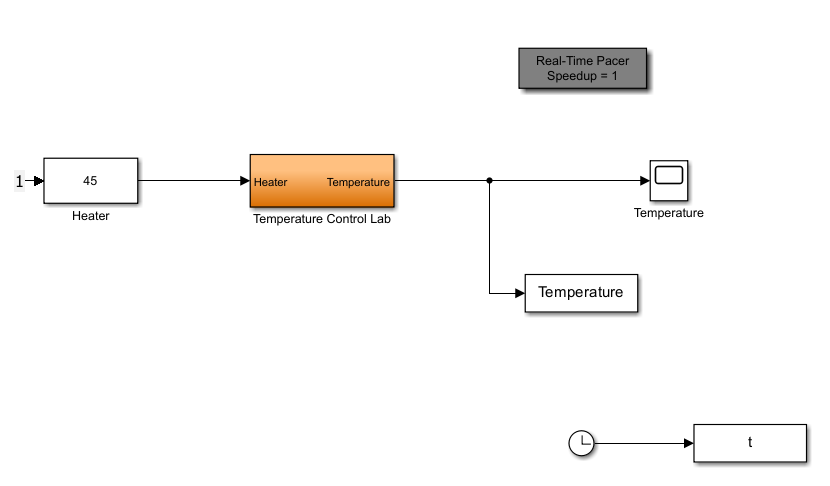

## FOPDT fitting

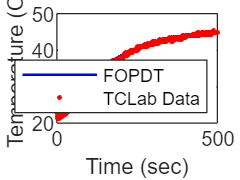

clc; clear all;
load ('data_TClab_fit.mat')

clf
figure(2)
K2 = 32;
Tau2 = 150;
Theta2 =  20;

n = 500;
time = linspace(1, n, n);
delay = ones(1, n);
for i=1:n
    if time(i)<Theta2
        delay(i) = 0;
    end
end
y = Temperature(4) + .75 * K2 * delay .* (1.0-exp(-(time-Theta2)/Tau2));
plot(time, y, 'b-', t,Temperature,'r.', "linewidth", 1)
legend('FOPDT', 'TCLab Data', 'location', 'southeast')
xlabel('Time (sec)')
ylabel('Temperature (C)')